clc
clearvars -except textures

if ~exist('textures', 'var')
    disp("Textures not loaded, loading textures...")
    load("textures\textures.mat");
    disp("done")
end

Textures not loaded, loading textures...


done


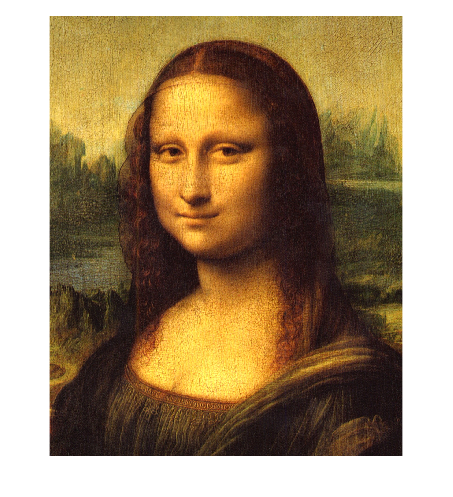


%segment image
image = im2double(imread("test_images\Mona_Lisa.jpg"));
imshow(image)

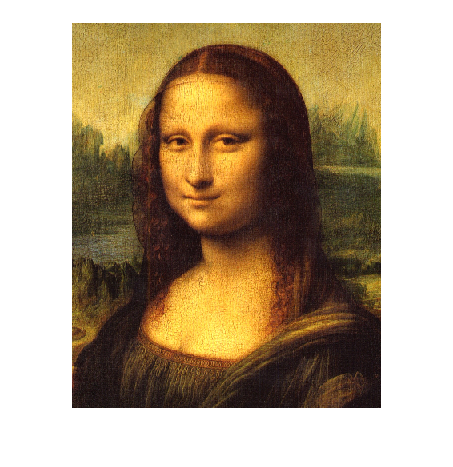

image = imresize(image, 0.2, "nearest");


imshow(image)

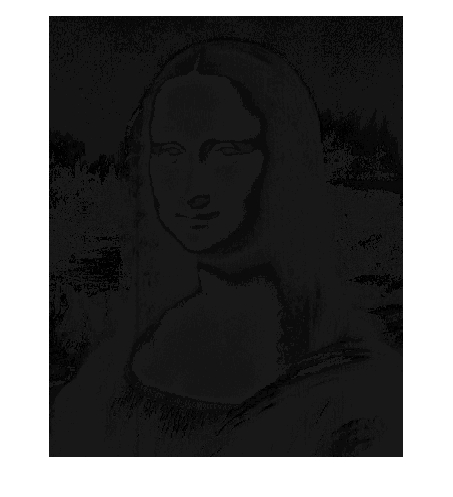


%Replace each color with texture id

id_map = uint8(zeros(size(image(:,:,1))));

for row = 1:size(image,1)
    for col = 1:size(image,2)

        current_pixel(:) = image(row,col,:);

        id = rgb2textureID(current_pixel, textures);

        id_map(row, col) = id;
    end
end

id_map = imresize(id_map, 1/0.2, "nearest");

% Recreate input image with textures
result = zeros(size(id_map,1), size(id_map,2), 3);
for row = 1:size(id_map,1)
    for col = 1:size(id_map,2)

        result(row,col,:) = getpixel(textures(id_map(row,col)).diffuse, row, col);
    end
end

imshow(id_map)

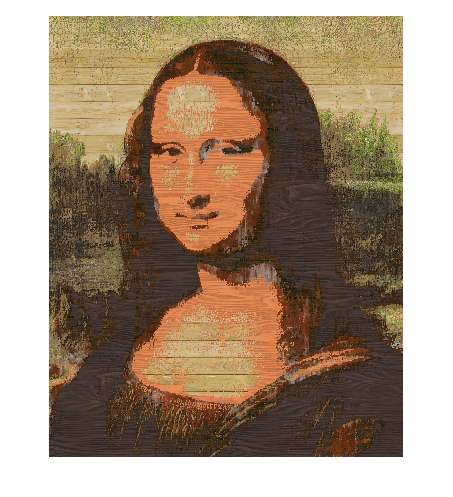

imshow(result)


size(image,1)

ans = 481

size(image,2)

ans = 386